# Classification Part I - Introduction to Classifiers

*Shira Lupkin - 2020*

## Types of Classification

Classification problems fall under the umbrella of *supervised *learning algortihms. The term "supervised" comes from the fact that, for each observation in the dataset, there is a known label that identifies the class to which a given observation belongs. When the classifier comes up with a putative solution, the output of the classifier is compared against these labels, and the algorithm is told which ones were correctly classified and which were not. That is the supervision; the known correct labels are used to steer the algorithm towards the best classifier.

This is in contrast with *unsupervised* learning methods such as PCA or clustering methods which do not require such labels (e.g., k-means); they try to find patterns or subgroups based on the statistical regularities within the observations. 

There are several  types of classifiers. Some, like logistic regression, can only be used to classify observations into two classes. Others, such as linear discriminant analysis and support vector machines are more flexible and can classify observations into two or more classes. For the sake of consistency, we are going to use the example of a support vector machine (SVM) to demonstrate cross-validation and model assessment. 

## Cross-Validation

The simplest classifier is a list of all observations that have label A. If an observation is in the list, the classifer says A, and B otherwise. This classifier works great for the data set used to define the list, but it is perfectly useless for new observations. This (extreme) example shows that classifier performance should always be tested on new data (i.e. data that were not used to define the classifier). This is called cross-validation. 

The basic principle behind cross validation is to split the data into a set of training data, on which the classifier is trained, and testing data which is fed to the trained classifier to see how accurately it classifies data that it has never encountered.  The three most common types of cross-validation are *hold-out*,* leave-one-out, *and *k-fold. *

### Hold-out

The first method we will discuss is the *hold-out *method. In this method, a certain percentage of the data are put aside as testing data and the remainder of the data is used to train the classifier. Since the data are only partitioned into two segments, this method is computationally inexpensive. However, this method is highly sensitive to the size of the partition. The larger the percentage of data held-out, the more generalizable the classifier will be. While this prevents overfitting the data, it often causes increased misclassication rates since the classifier was trained with less data. This is  worse if the data are noisy. In this case, the fraction of held-out data may be a very poor representation of the whole dataset. Since this method is so dependent on which data are held-out, if you randomly select the same percentage of data some number of times, you will likely get different results each time you run it. 

### Leave-One-Out

In contrast to the hold-out method in which a model is fit to one subset of data and tested on another, l*eave-one-out cross-valudation* (LOOCV) fits the data n-number of times where n is the number of observations. Each time the model is fit to all but one observation and then tested on the single held-out observation.  This method is computationally expensive since it fits the classifier a number of times equal to the number of observations in the data set. As you can imagine, this may not be ideal for very large datasets. 

### K-Fold

*K-fold *cross validation is similar to LOOCV, in fact, LOOCV is a special-case of *k-fold. *In k-fold cross validation, the data are split into k roughly equally sized segments. For each iteration of k-fold cross validation, the classifier is fit to all but one fold and tested on the others. This is repeated k number of times. The most common values of k are 5 & 10. In Matlab, 10-fold is the default method of cross validation. k-fold has all of the advantages of LOOCV, but with a lower computational cost. The results of the two methods, though, are often highly similar. 

## Classifier Performance

An important aspect of classification is assessing the accuracy of the classifiers. Two common methods of visualizing classifier performance are *confusion matrices* and *ROC curves*. 

### Confusion Matrices

Confusion matrices show classifier performance by creating a matrix containing the number of correct classifications on the main diagonal and misclassifications on the off-diagonal. In Matlab, the columns in this matrix represent the predicted classes, and the rows are the true classes. Confusion matrices are helpful in identifying *where* misclassifications are occuring. 

### Receiver Operating Characteristics (ROC) & Area Under the Curve (AUC)

ROC curves are plots that show the rate of false positives against the rate of true positives. In addition to the ROC curve itself, ROCs are typically plotted along with a 'unity' line which represents the classification that you would expect by chance. Classifier performance is assessed by calculating the area under this curve (AUC). For a binary classifier, chance-performance would result in an AUC of 0.5 (which is the AUC of the unity line). The closer the AUC is to 1, the better the classifier's performance. 

## Putting it all together

In the following example we are going to fit an SVM (details on this procedure are in the second classification MLX), cross-validate the classifier using several methods, and assess the classifiers' performance across all cross-validation methods using an ROC curve and calculating the area under the curve.

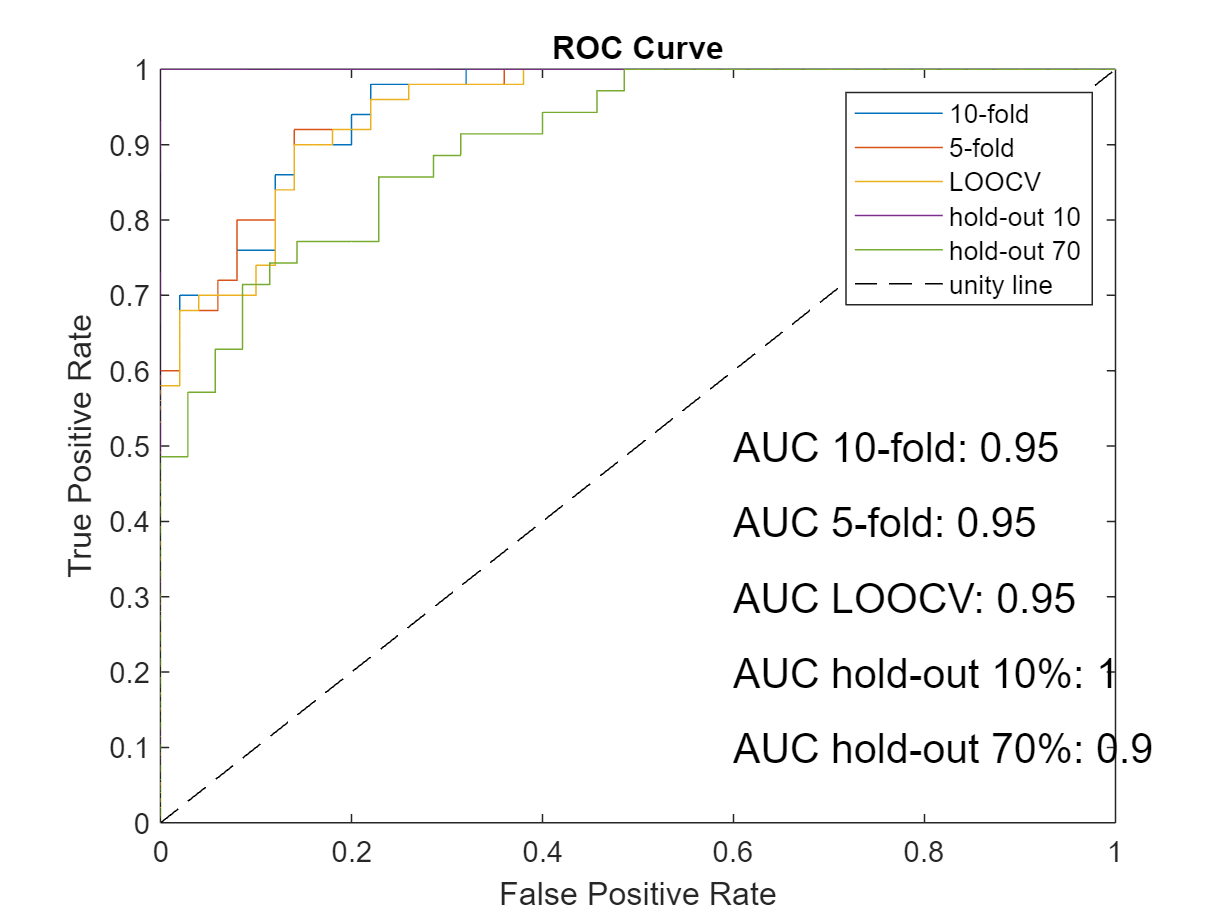

clear;clc
clf
load ../data/tutorial5
% Determine the SVM classifier by passing data and labels.
mdlSVM = fitcsvm(data,labels);

% cross validate model with 10-fold validation
kfold10 = crossval(mdlSVM);
[~,scores10] = kfoldPredict(kfold10);

% cross validate model with 5-fold validation
kfold5 = crossval(mdlSVM,'kfold',5);
[~,scores5] = kfoldPredict(kfold5);

% cross validate model with LOOCV validation
loocv = crossval(mdlSVM,'leaveout','on');
[~,scoresLoo] = kfoldPredict(loocv);

% cross validate model with hold out validation 10%
ho10 = crossval(mdlSVM,'holdout',0.1);
[~,scoresH10] = kfoldPredict(ho10);

% cross validate model with hold out validation 70%
ho70 = crossval(mdlSVM,'holdout',0.7);
[~,scoresH70] = kfoldPredict(ho70);

% calculate ROC
[Xsvm10,Ysvm10,Tsvm10,AUC10] = perfcurve(labels,scores10(:,2),1);
[Xsvm5,Ysvm5,Tsvm5,AUC5] = perfcurve(labels,scores5(:,2),1);
[XsvmL,YsvmL,TsvmL,AUCL] = perfcurve(labels,scoresLoo(:,2),1);
[XsvmH10,YsvmH10,TsvmH10,AUCH10] = perfcurve(labels,scoresH10(:,2),1);
[XsvmH70,YsvmH70,TsvmH70,AUCH70] = perfcurve(labels,scoresH70(:,2),1);

% plot ROC curve
plot(Xsvm10,Ysvm10); hold on
plot(Xsvm5,Ysvm5);
plot(XsvmL,YsvmL);
plot(XsvmH10,YsvmH10);
plot(XsvmH70,YsvmH70);
plot(0:0.1:1,0:0.1:1,'k--')
xlabel 'False Positive Rate'
ylabel 'True Positive Rate'
title('ROC Curve')

% add AUCs
text(0.6,0.5,['AUC 10-fold: ',num2str(round(AUC10,2))],'FontSize',14)
text(0.6,0.4,['AUC 5-fold: ',num2str(round(AUC5,2))],'FontSize',14)
text(0.6,0.3,['AUC LOOCV: ',num2str(round(AUCL,2))],'FontSize',14)
text(0.6,0.2,['AUC hold-out 10%: ',num2str(round(AUCH10,2))],'FontSize',14)
text(0.6,0.1,['AUC hold-out 70%: ',num2str(round(AUCH70,2))],'FontSize',14)
legend('10-fold','5-fold','LOOCV','hold-out 10', 'hold-out 70','unity line')

Run through the code in the previous section multiple times. You should notice that the AUC values for the k-fold and LOOCV methods do not really change, while the two hold out methods are less stable with the 70% hold-out method being the most variable. This method is (often) the least accurate. 

## Resources

**Books**

Introduction to Statistical Learning with Applications in R (ISLR): [http://faculty.marshall.usc.edu/gareth-james/ISL/ISLR%20Seventh%20Printing.pdf](http://faculty.marshall.usc.edu/gareth-james/ISL/ISLR%20Seventh%20Printing.pdf) 

Elements of Statistical Learning: [https://web.stanford.edu/~hastie/ElemStatLearn/printings/ESLII_print12_toc.pdf](https://web.stanford.edu/~hastie/ElemStatLearn/printings/ESLII_print12_toc.pdf) 

**Associated Videos**

[https://www.r-bloggers.com/2014/09/in-depth-introduction-to-machine-learning-in-15-hours-of-expert-videos/](https://www.r-bloggers.com/2014/09/in-depth-introduction-to-machine-learning-in-15-hours-of-expert-videos/)